reader1 = VideoReader("ShakyStreet.avi");
reader2 = VideoReader("simpleStabilizedVideo.avi");
writer = VideoWriter("Finalvideo.avi");

idx = 55 

idx = 55

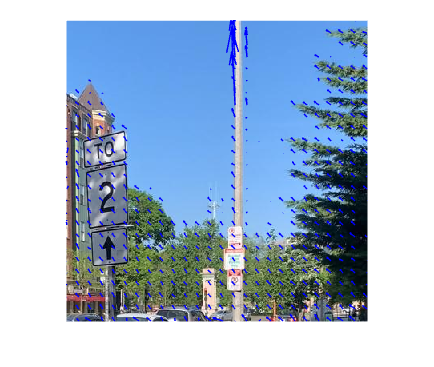

frame55_1 = read(reader1,idx);
frame55_2 = read(reader2,idx);


flow = opticalFlowFarneback;

estimateFlow(flow,im2gray(frame55_1));
frame56_1 = read(reader1,idx+1);
estimation = estimateFlow(flow,im2gray(frame56_1));

imshow(frame56_1)
hold on
plot(estimation, "DecimationFactor", [15 15], "ScaleFactor",7)
hold off

mean(mean(estimation.Magnitude))

ans = single
0.6327

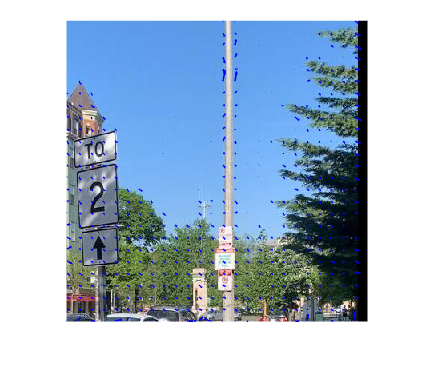

estimateFlow(flow,im2gray(frame55_2));
frame56_2 = read(reader2,idx+1);
estimation = estimateFlow(flow,im2gray(frame56_2));

imshow(frame56_2)
hold on
plot(estimation, "DecimationFactor", [15 15], "ScaleFactor",7)
hold off


mean(mean(estimation.Magnitude))

ans = single
0.3294